# ASEN 3128 Homework 5

#### Ryan Hughes, Ponder Stine, William Watkins

## Problem 1

g=9.81; %m/s^2
k1=1.6e-3;
k2=3.62e-3;
Ix=5.8e-5;
Iy=7.2e-5;

### Eigenvalues at Varying k3 Gains

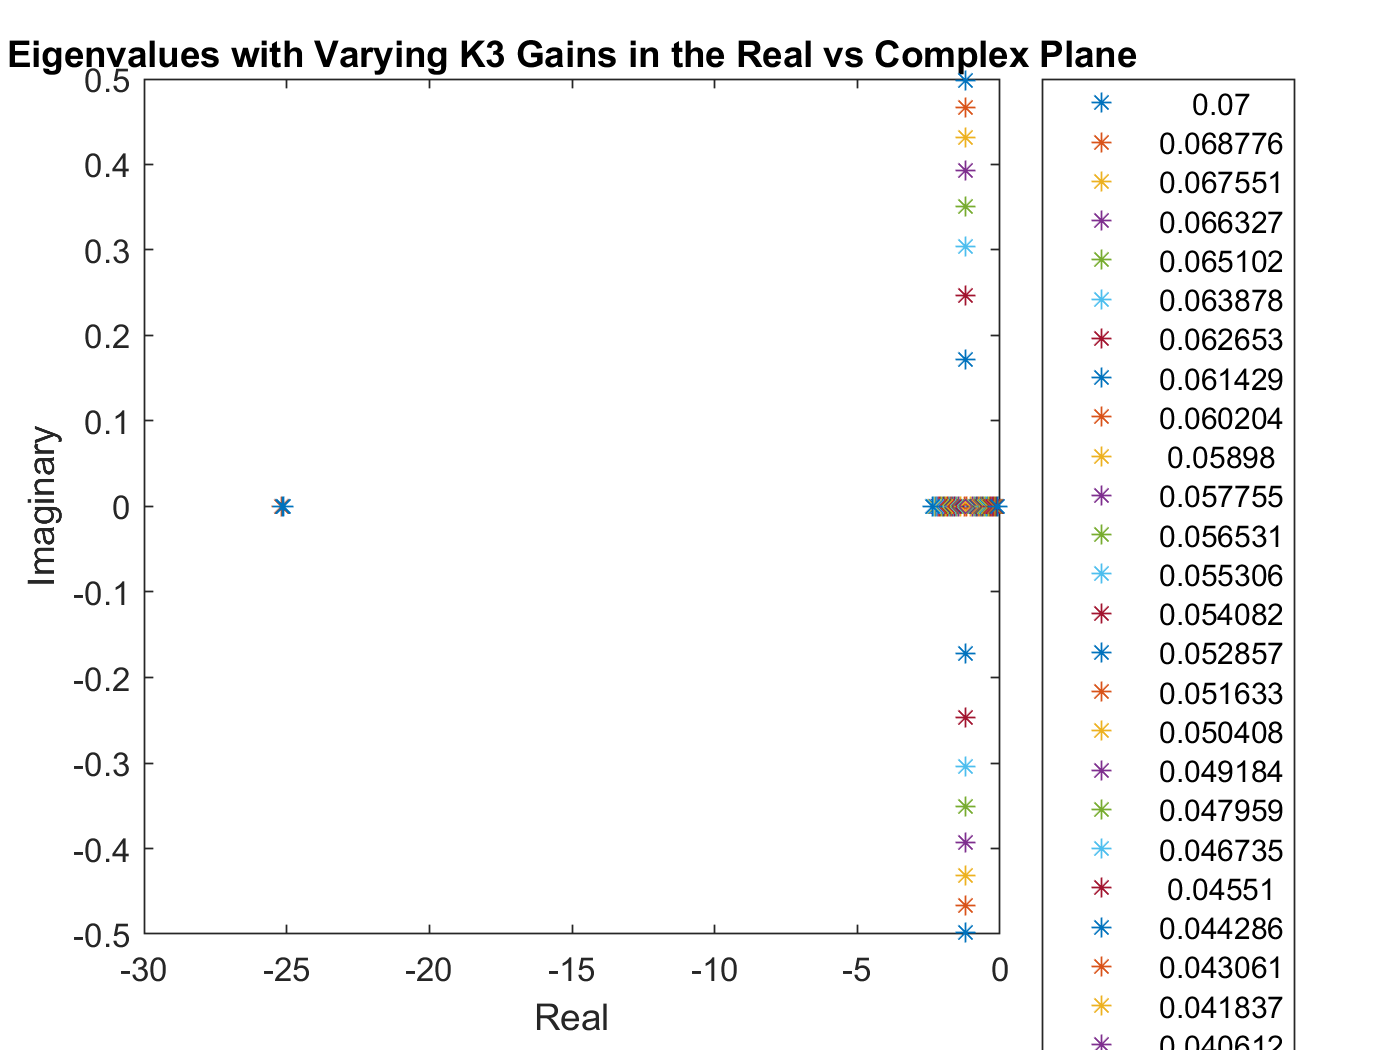

%create a vector of varying k3 gains to test
k3=linspace(7e-2,1e-2,50);

%preallocate space for eigenvalues of k3s
e=zeros(3,length(k3));

%for each k3 gain value
for i=1:length(k3)
    
    %A matrix
    A=[-k1/Ix,-k2/Ix,-k2*k3(i)/Ix;...]
        1,0,0;...
        0,g,0];
    
    %eigenvalues of the A matrix
    e(:,i)=eig(A);
    
end

%plot eigenvalues in real vs imaginary plane
plot(real(e),imag(e),'*')
title('Eigenvalues with Varying K3 Gains in the Real vs Complex Plane')
xlabel('Real')
ylabel('Imaginary')
legend(num2str(k3.'),'Location','bestOutside' )

### Settling Time for Selected gains

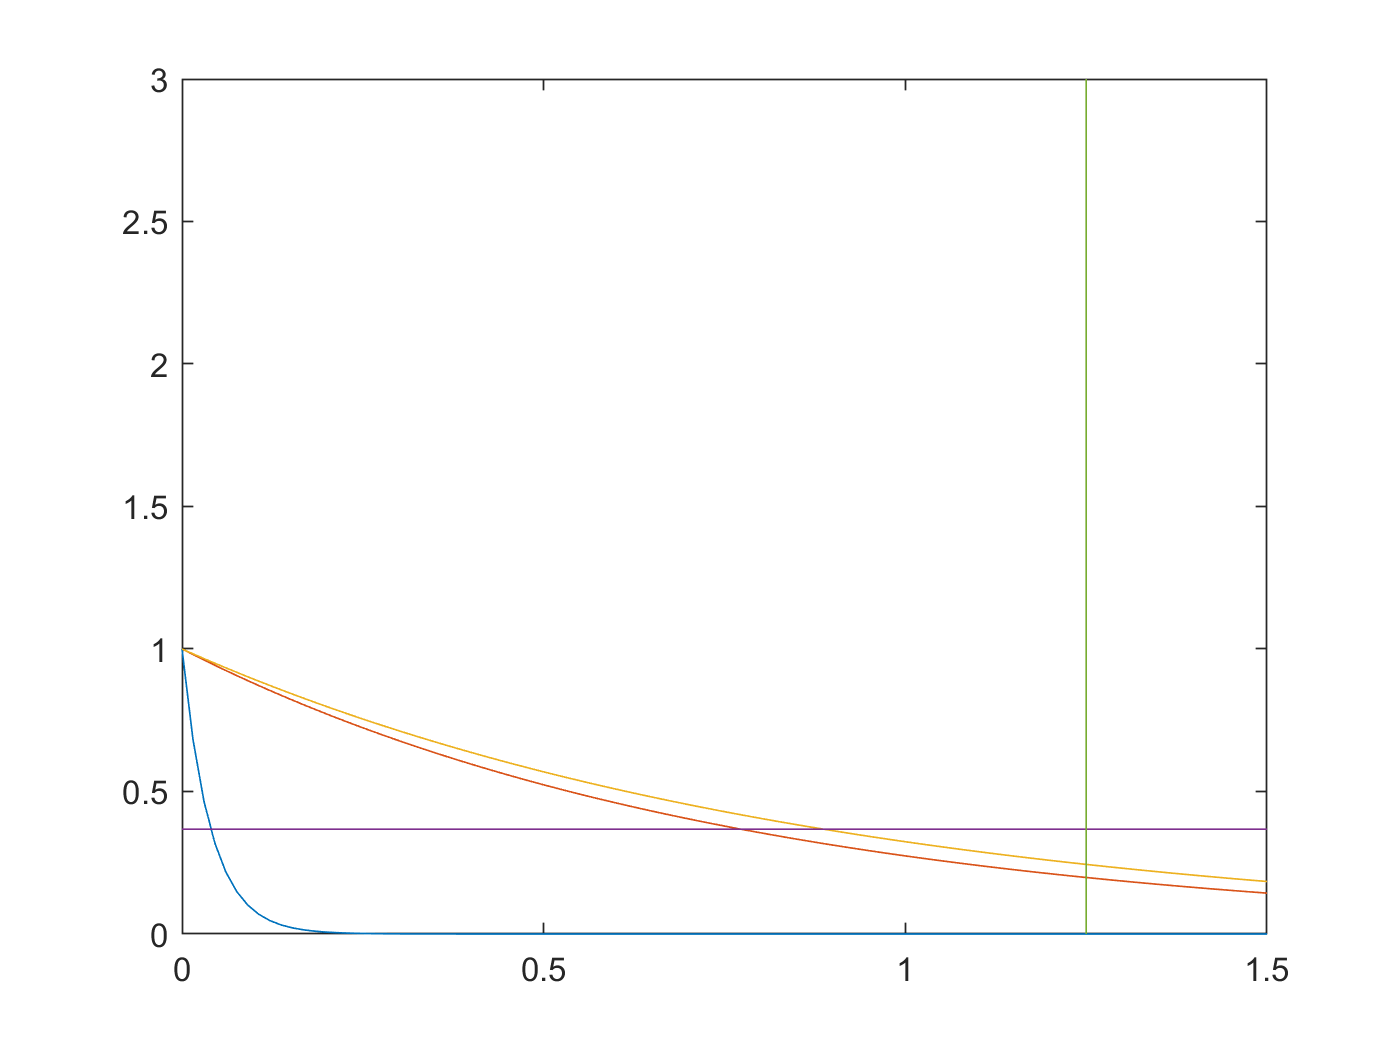

%We selected a gain k3 that had 3 real, negative eigenvalues and all
%eigenvalues <1/1.25 to meet our time response requirements
k3=6e-2;

%create A matrix with our k3 gain
A=[-k1/Ix,-k2/Ix,-k2*k3/Ix;...]
    1,0,0;...
    0,g,0];

%eigenvalues of our A matrix
e_fin=eig(A);

%response time with set of gains
tau=-1./(e_fin);

%create time vector for response plotting
t=linspace(0,1.5,100);

%calcuate response due to each eigenvalue/modality
y1=exp(e_fin(1)*t);
y2=exp(e_fin(2)*t);
y3=exp(e_fin(3)*t);

%plot responses of different modalities and time requirements of sub 37% in
%1.25 sec
plot(t,y1)
hold on
plot(t,y2)
plot(t,y3)
plot([0,1.5],[exp(-1),exp(-1)])
plot([1.25,1.25],[0,3])


%From last week, the lateral gains over Ix equals the longitudinal gains
%over Iy. Calculating the longitudinal gains from the lateral gains would
%give the same time response which meets our requirements.
k4=k1*Iy/Ix;
k5=k2*Iy/Ix;
k6=k3*Iy/Ix;

To determine the values of k3 and k6, the proportional gains on the components of velocity in the x and y directions, first we created the 3x3 characteristic matrix for our given control law. We used the same k1 and k2 gains from last week, and calculated the eigenvalues of the characteristic matrix with a set of varying k3 gains. We then chose a value for k3 that produces 3 real, negative eigenvalues for the characteristic matrix. These values need to be real and negative to give a stable control law that meets our assignment requirements. Then, we needed to ensure that the modal time response of each of the eigenvalues met our given requirements of reaching 37% of a starting value in less than 1.25 seconds. All 3 of the modal responses, graphed by y=e^(lambda*t), have a time response that meets our requirements. We know from last week that the ratio of the lateral gains to the moment of inertia about the x axis is equal to that of the longitudinal gains to the moment of inertia about the y axis. We can then calculate k6 from k3 and know that all our gains meet the requirements for our assignment.

### Set up the Workspace

close all;
clear all;
clc;

### Declare Constants

global g I_x I_y I_z m R G_body g_body fb L_BE L_EB

g = 9.81; % [m/s^2], acceleration of gravity
m = 0.068; % [kg], mass of the quadcopter
R = 0.060; % [m], distance from CG to motors
I_x = 5.8 * 10 ^ (-5); % [kg*m^2], moment of inertia about x-axis
I_y = 7.2 * 10 ^ (-5); % [kg*m^2], moment of inertia about y-axis
I_z = 1.0 * 10 ^ (-4); % [kg*m^2], moment of inertia about z-axis
eta = 1 * 10 ^ (-3); % [N/(m/s)^2], drag per velocity squared
alpha = 2 * 10 ^ (-6); % [N*m/(rad/s)^2], moment per rate of rotation squared
k = 0.0024; % [N*m/N], moment per force of motors

### Initialize variables

x = 0; % [m], initial North position
y = 0; % [m], initial East position
z = -5; % [m], initial Down position
inertialVelocity = [0; 0; 0];
p = 0;
q = 0;
r = 0;
phi = 0;
theta = 0;
psi = 0;

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), ...
    cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
    cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), ...
    cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
    -sin(theta),    sin(phi) * cos(theta),     cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity = L_BE * inertialVelocity;
u = bodyVelocity(1);
v = bodyVelocity(2);
w = bodyVelocity(3);

### Preparing for the ODE45

initialState = [x y z u v w p q r phi theta psi];
tSpan = 0:0.01:10;

### Calling ODE 45

[t,y] = ode45('quadcopterSimulationLinControl', tSpan, initialState);

### Plotting the results

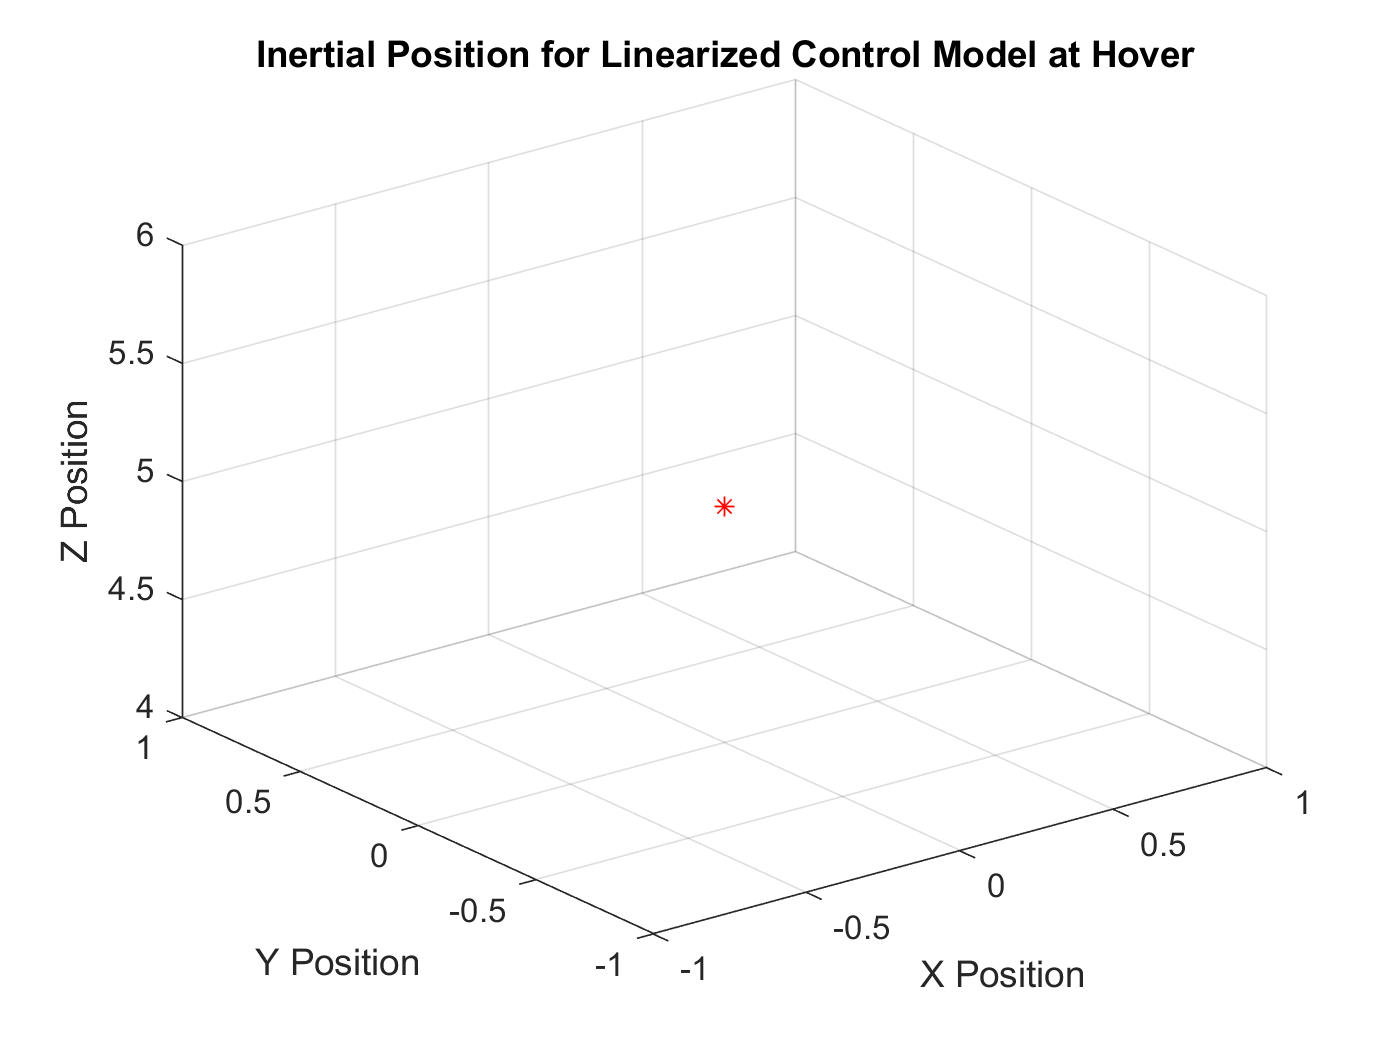

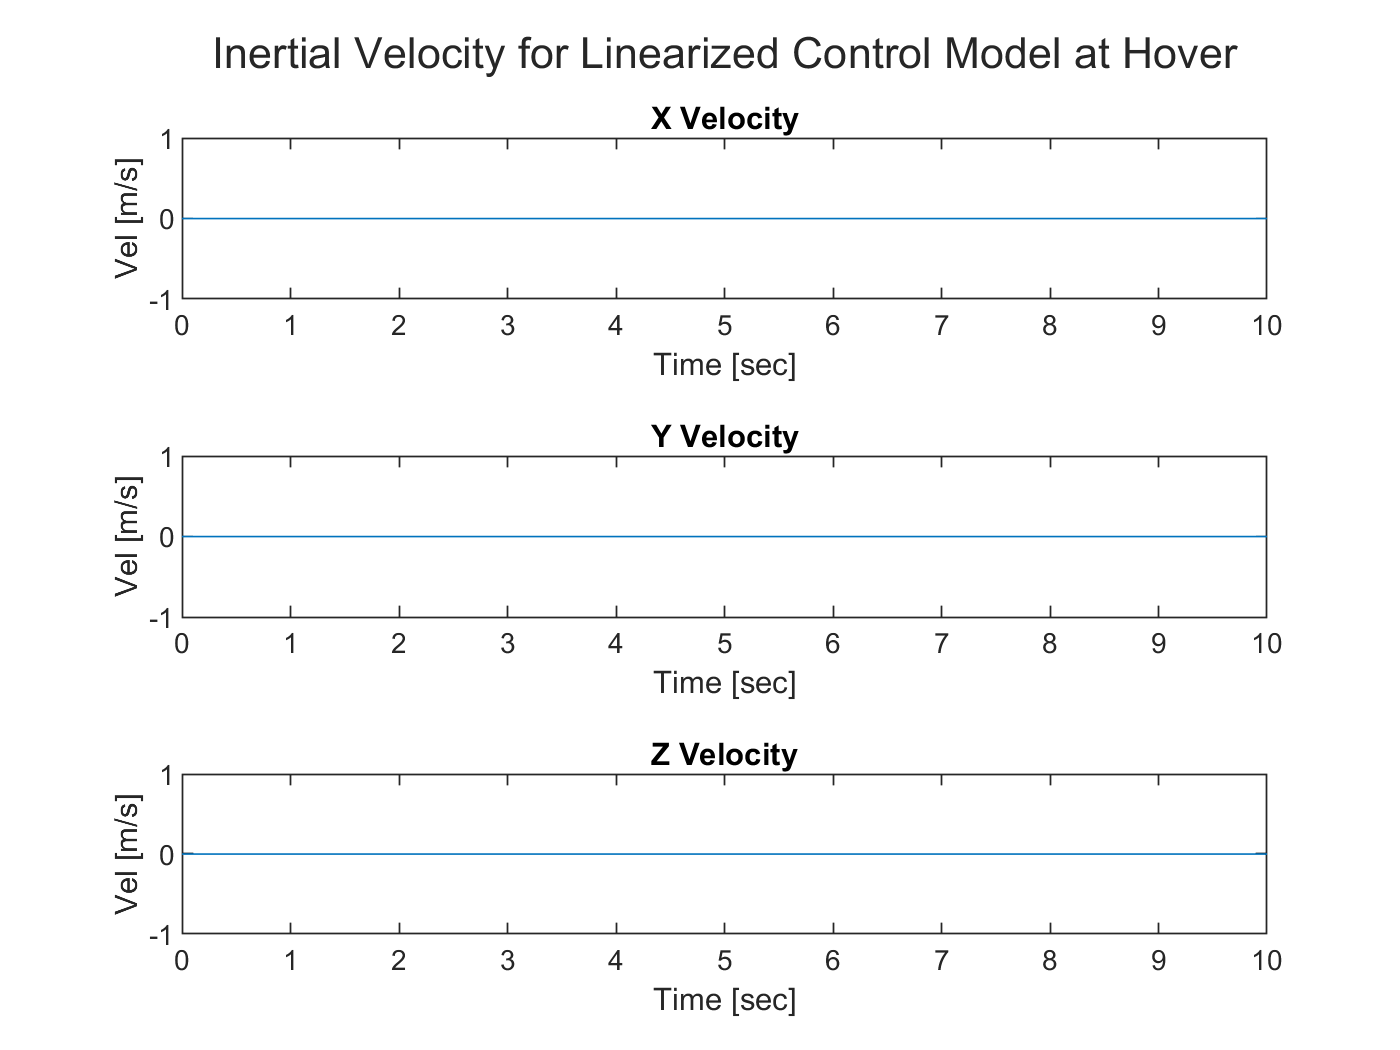

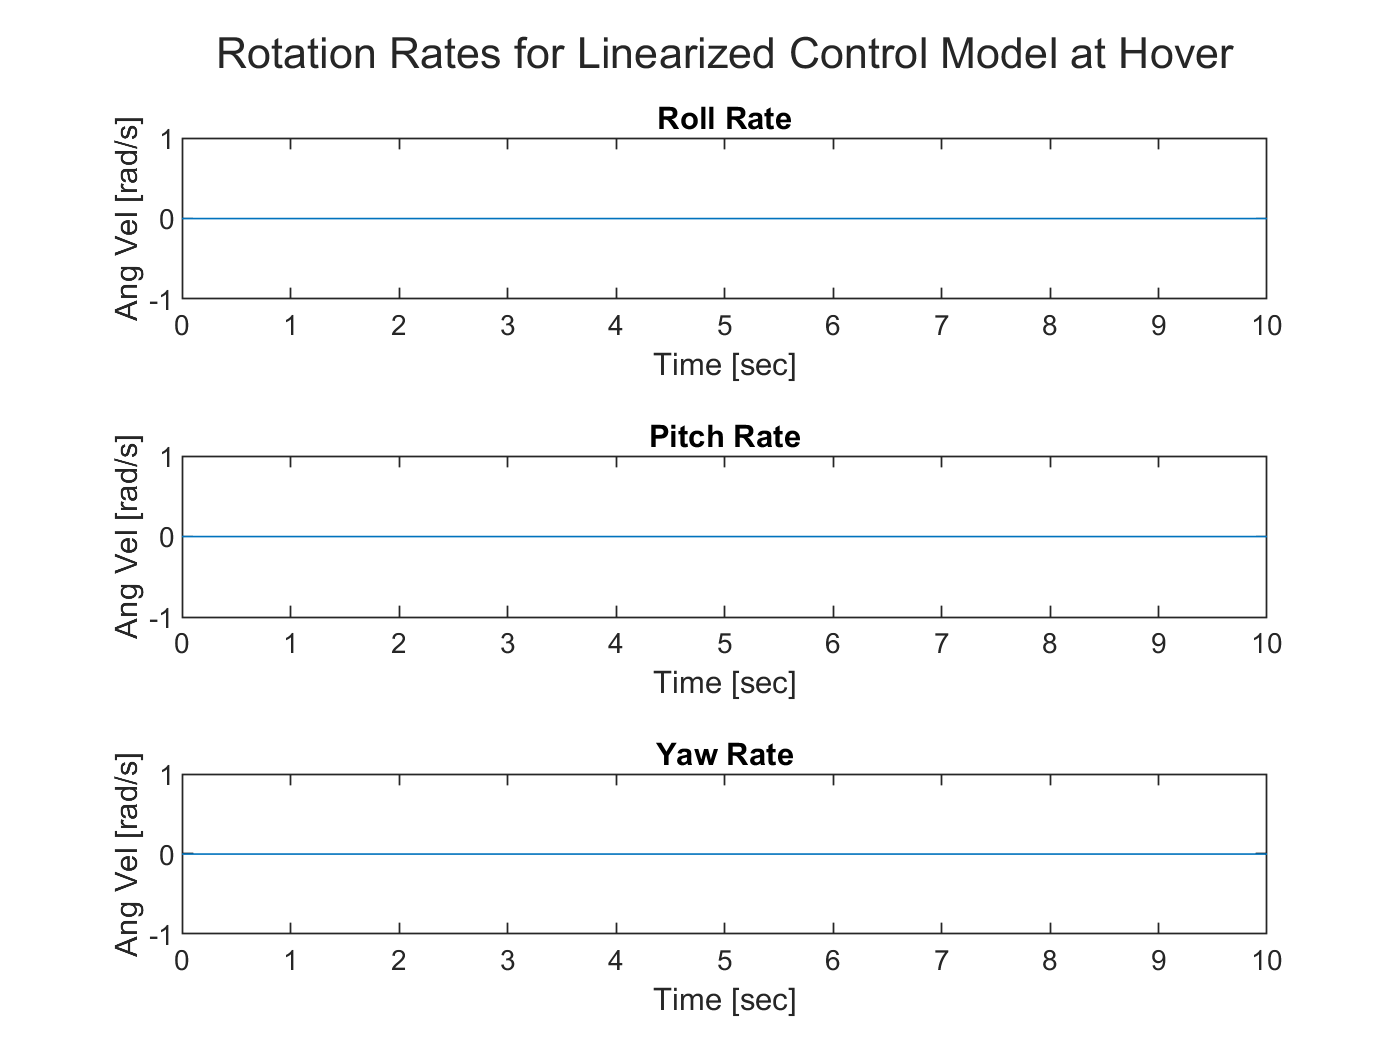

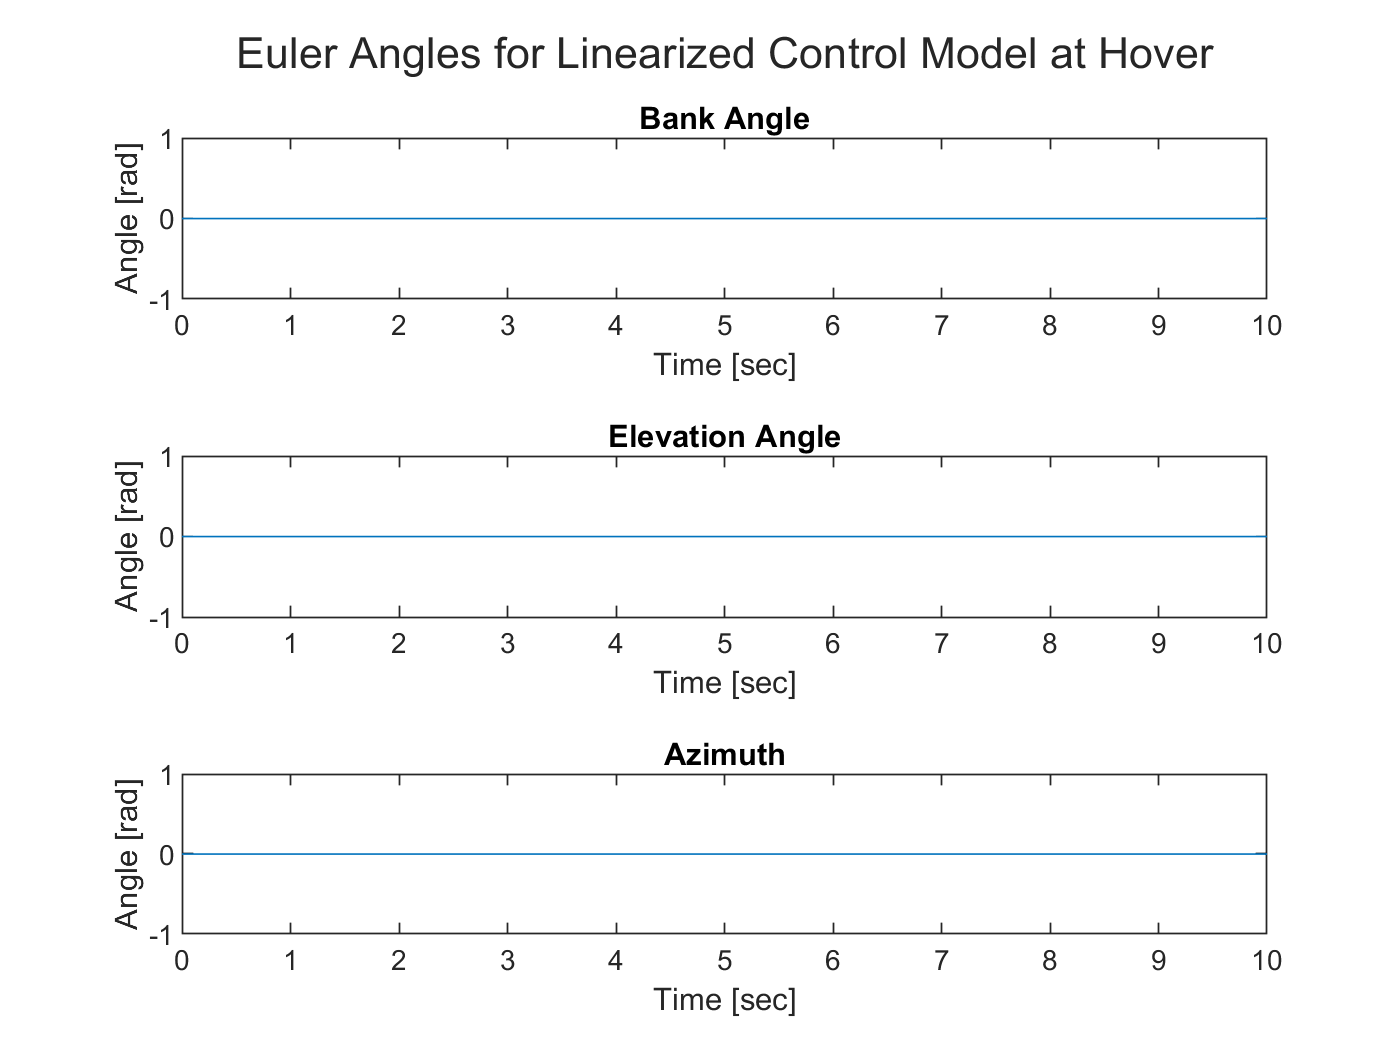

plutter(t,y,'Linearized Control Model at Hover')

## Problem 2

[tmove, ymove] = ode45('quadcopterSimulationLinOpenLoop', [tSpan 10.01:.01:20], initialState);

### Plotting the Results

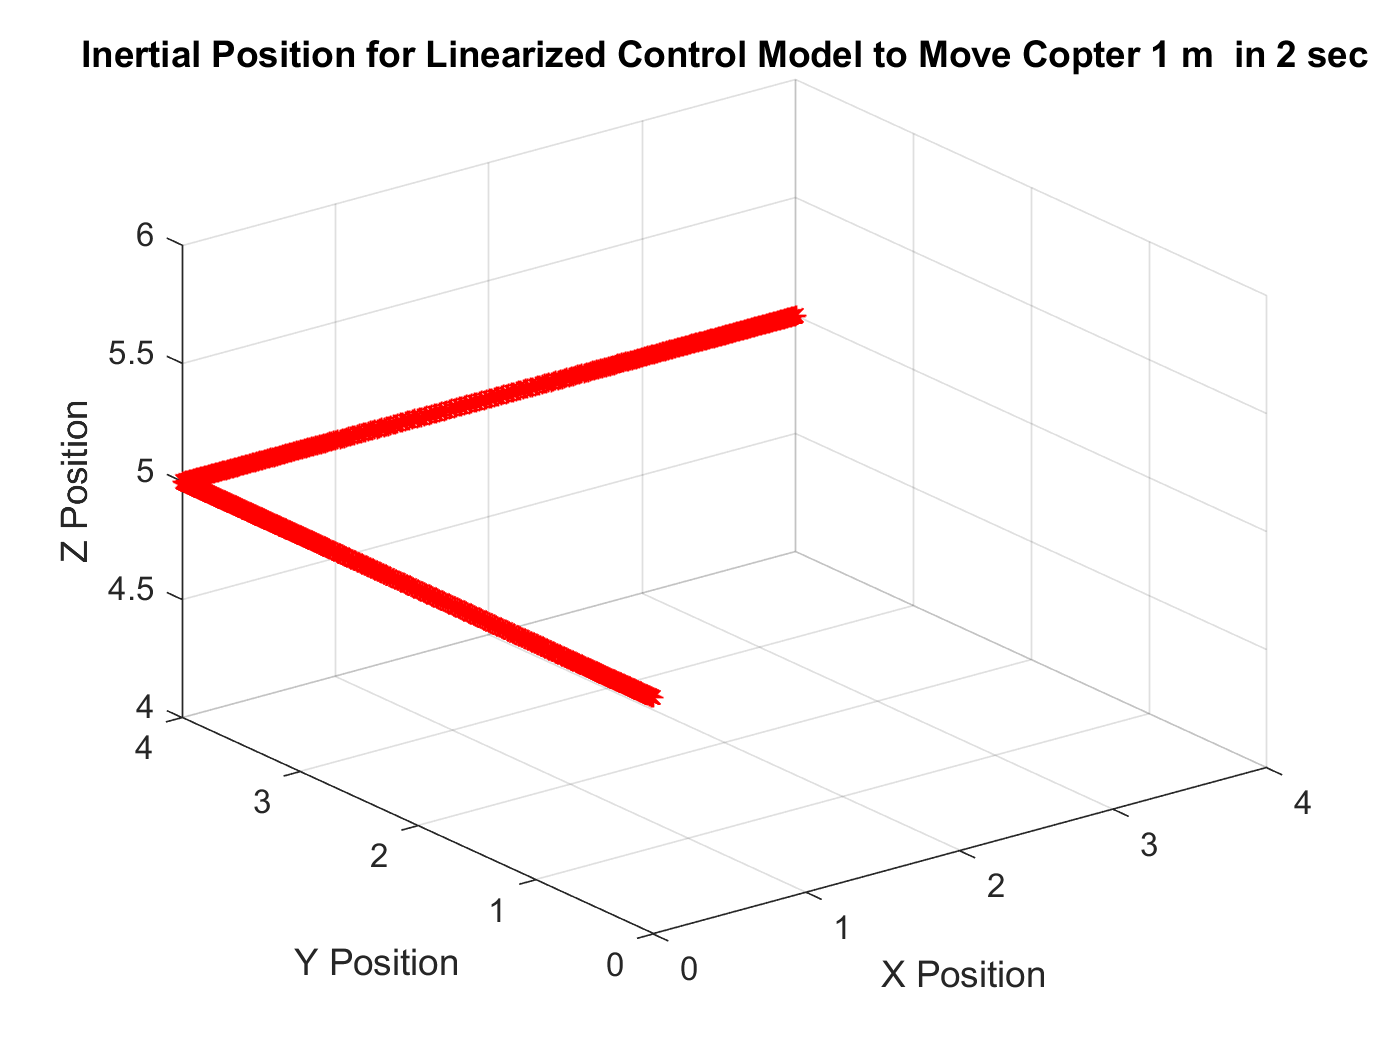

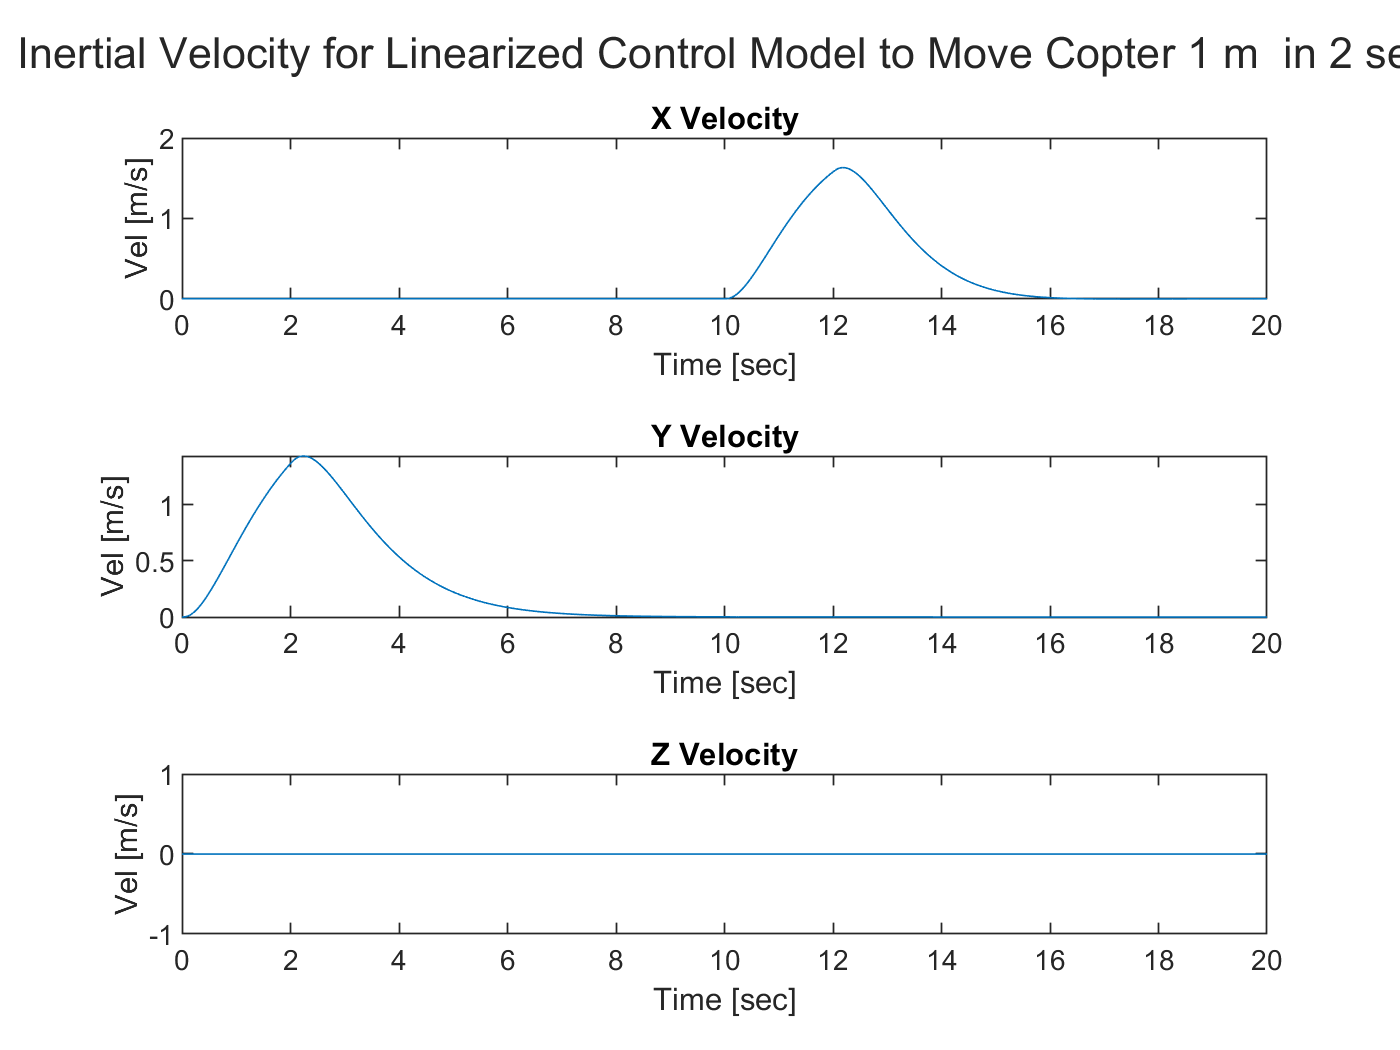

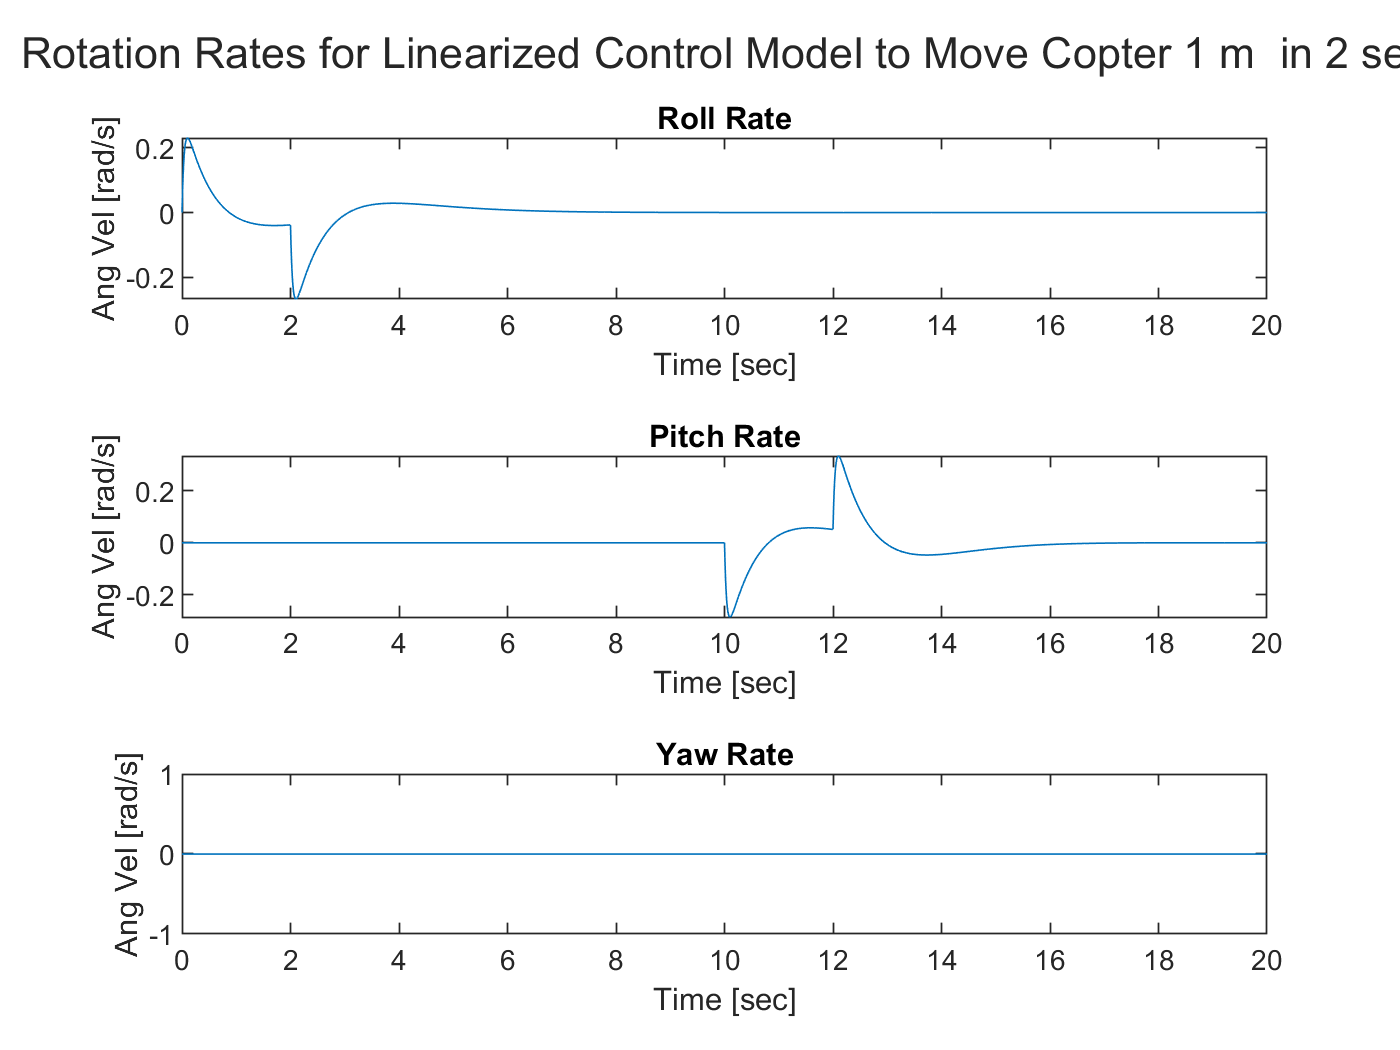

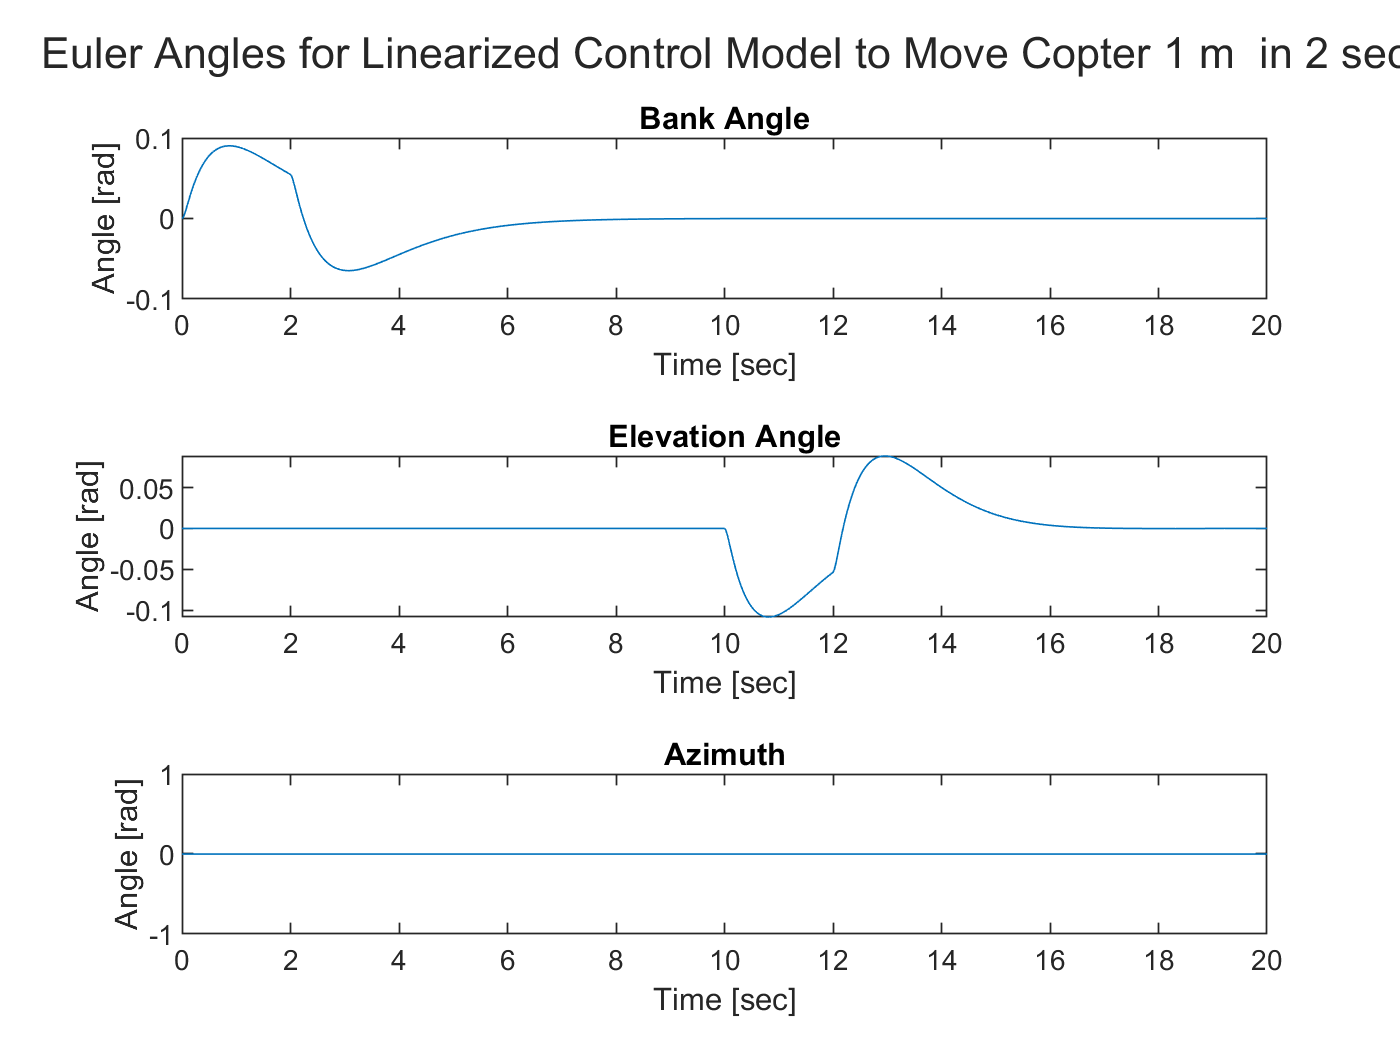

plutter(tmove, ymove, 'Linearized Control Model to Move Copter 1 m  in 2 sec');

y1 = find(ymove(:,2) > 1, 1);
fprintf('The copter reaches 1 meter in the +y-direction at t = %4.2f seconds.', tmove(y1));

The copter reaches 1 meter in the +y-direction at t = 1.79 seconds.

The copter stops moving in the +y direction when t = 2 seconds, and starts moving in the +x direction at t = 10 seconds.

x1 = find(ymove(:,1) > 1, 1);
fprintf('The copter reaches 1 meter in the +x-direction at t = %4.2f seconds.', tmove(x1));

The copter reaches 1 meter in the +x-direction at t = 11.65 seconds.

## Problem 3

Comparing the Mambo copter to the simulation.

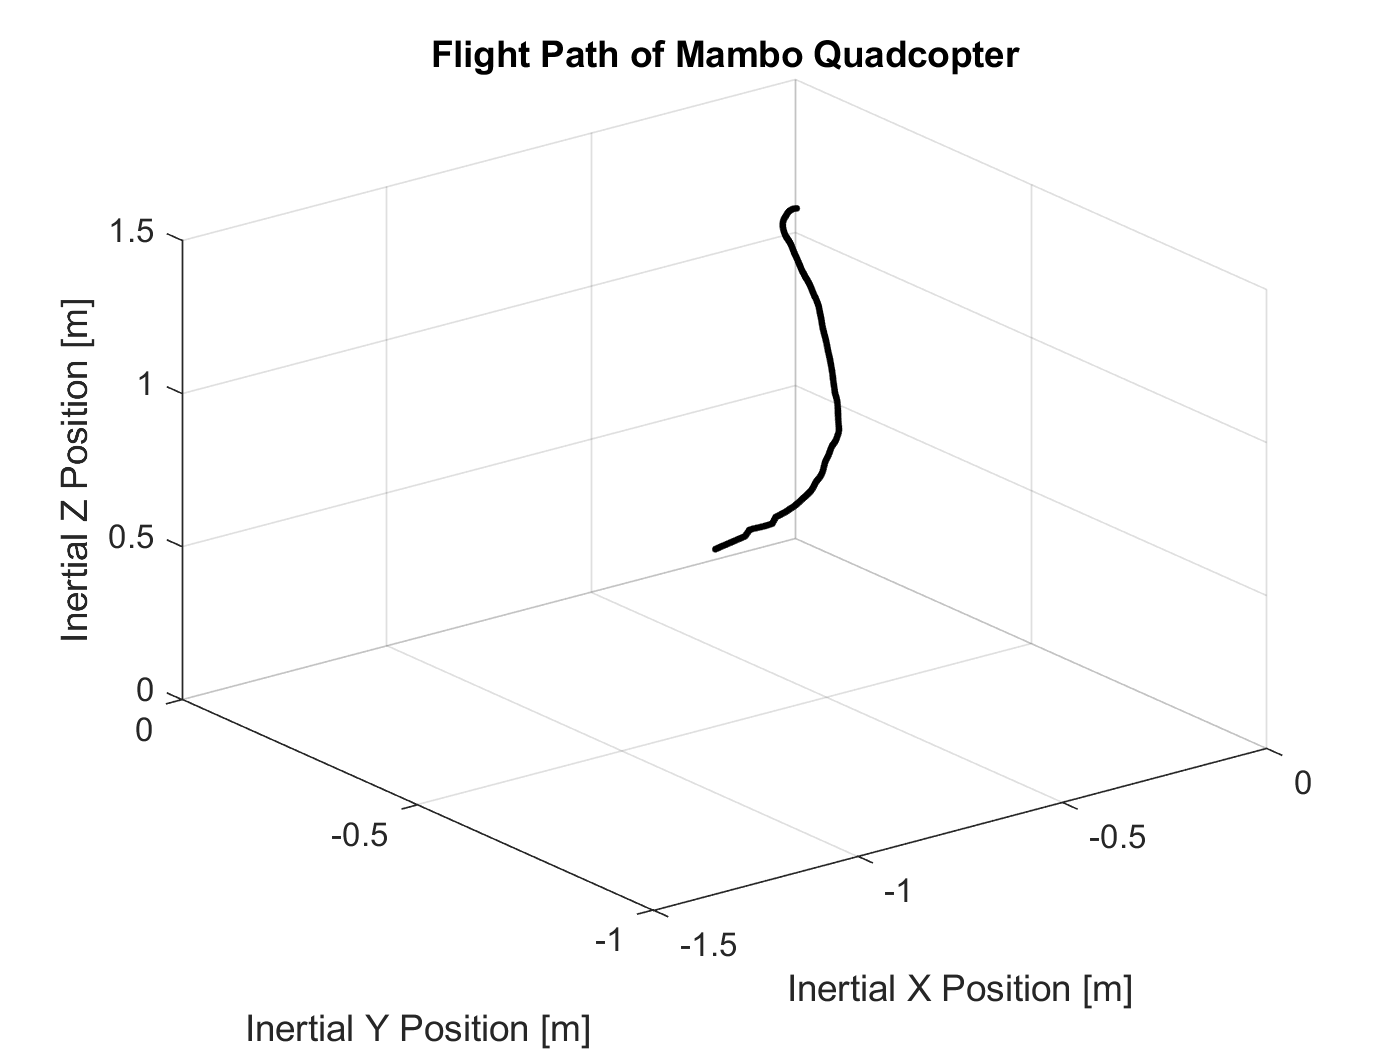

load('RSdata_two_1531.mat');
time=rt_estimatedStates.time(1585:end) - rt_estimatedStates.time(1585);
x=rt_estimatedStates.signals.values(1585:end,1);
y=rt_estimatedStates.signals.values(1585:end,2);
z=rt_estimatedStates.signals.values(1585:end,3);
yaw=rt_estimatedStates.signals.values(1585:end,4);
pitch=rt_estimatedStates.signals.values(1585:end,5);
roll=rt_estimatedStates.signals.values(1585:end,6);
Vx=rt_estimatedStates.signals.values(1585:end,7);
Vy=rt_estimatedStates.signals.values(1585:end,8);
Vz=rt_estimatedStates.signals.values(1585:end,9);
p=rt_estimatedStates.signals.values(1585:end,10);
q=rt_estimatedStates.signals.values(1585:end,11);
r=rt_estimatedStates.signals.values(1585:end,12);

figure()
plot3(x,y,-z,'.k')
title('Flight Path of Mambo Quadcopter')
xlabel('Inertial X Position [m]')
ylabel('Inertial Y Position [m]')
zlabel('Inertial Z Position [m]')
zlim([0 1.5])
grid on

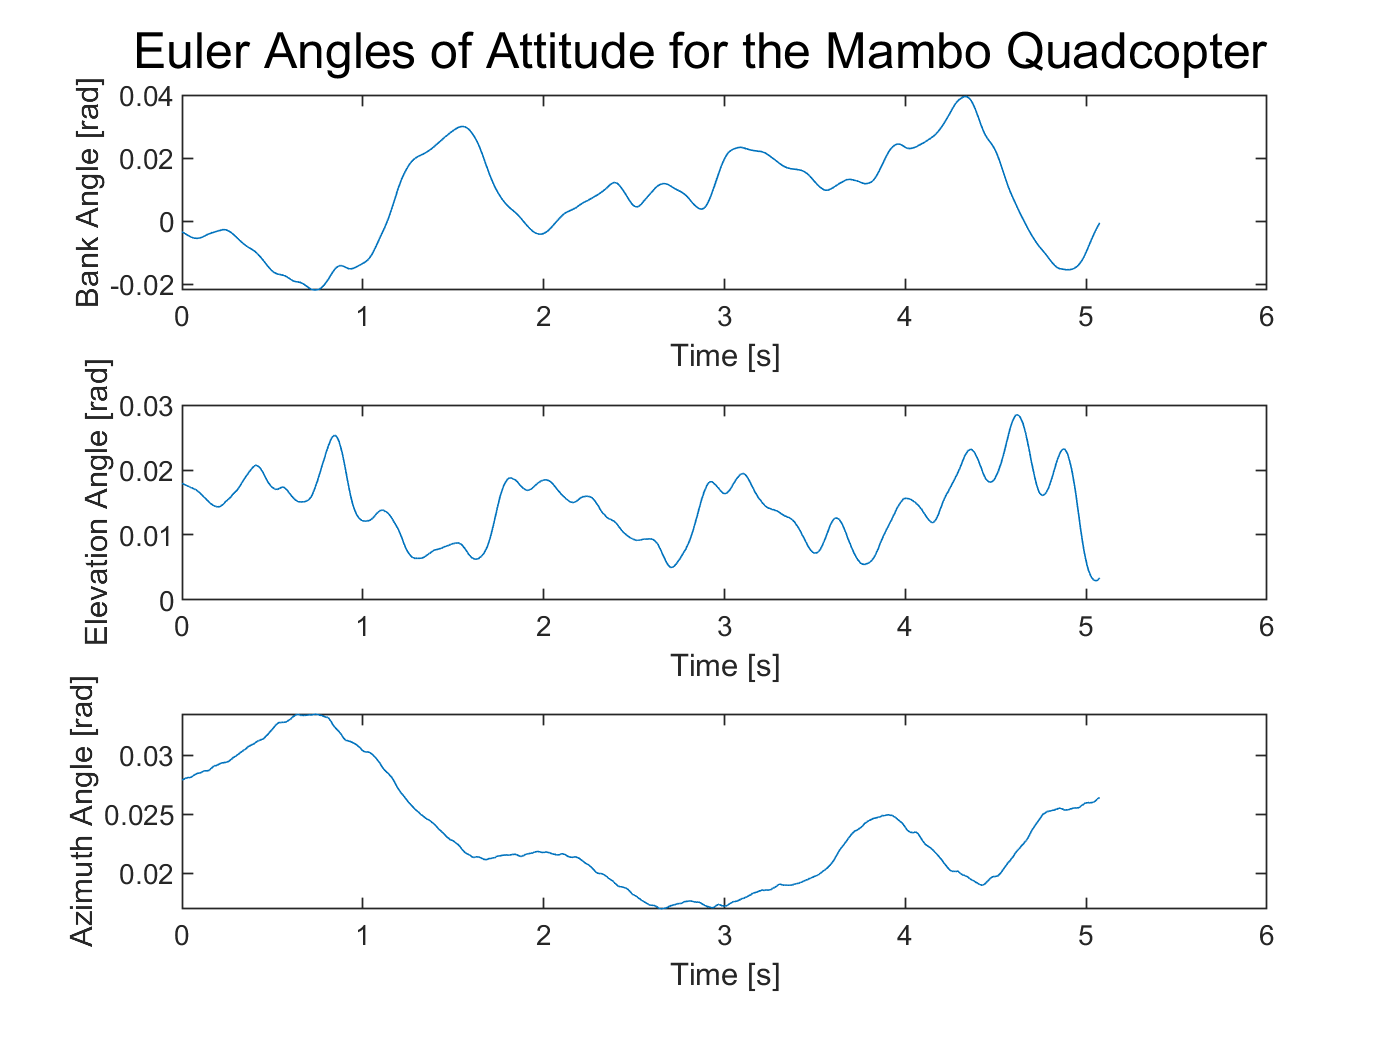


figure()
subplot(3,1,1)
plot(time,roll)
xlabel('Time [s]')
ylabel('Bank Angle [rad]')

subplot(3,1,2)
plot(time,pitch)
xlabel('Time [s]')
ylabel('Elevation Angle [rad]')

subplot(3,1,3)
plot(time,yaw)
xlabel('Time [s]')
ylabel('Azimuth Angle [rad]')

sgtitle('Euler Angles of Attitude for the Mambo Quadcopter')

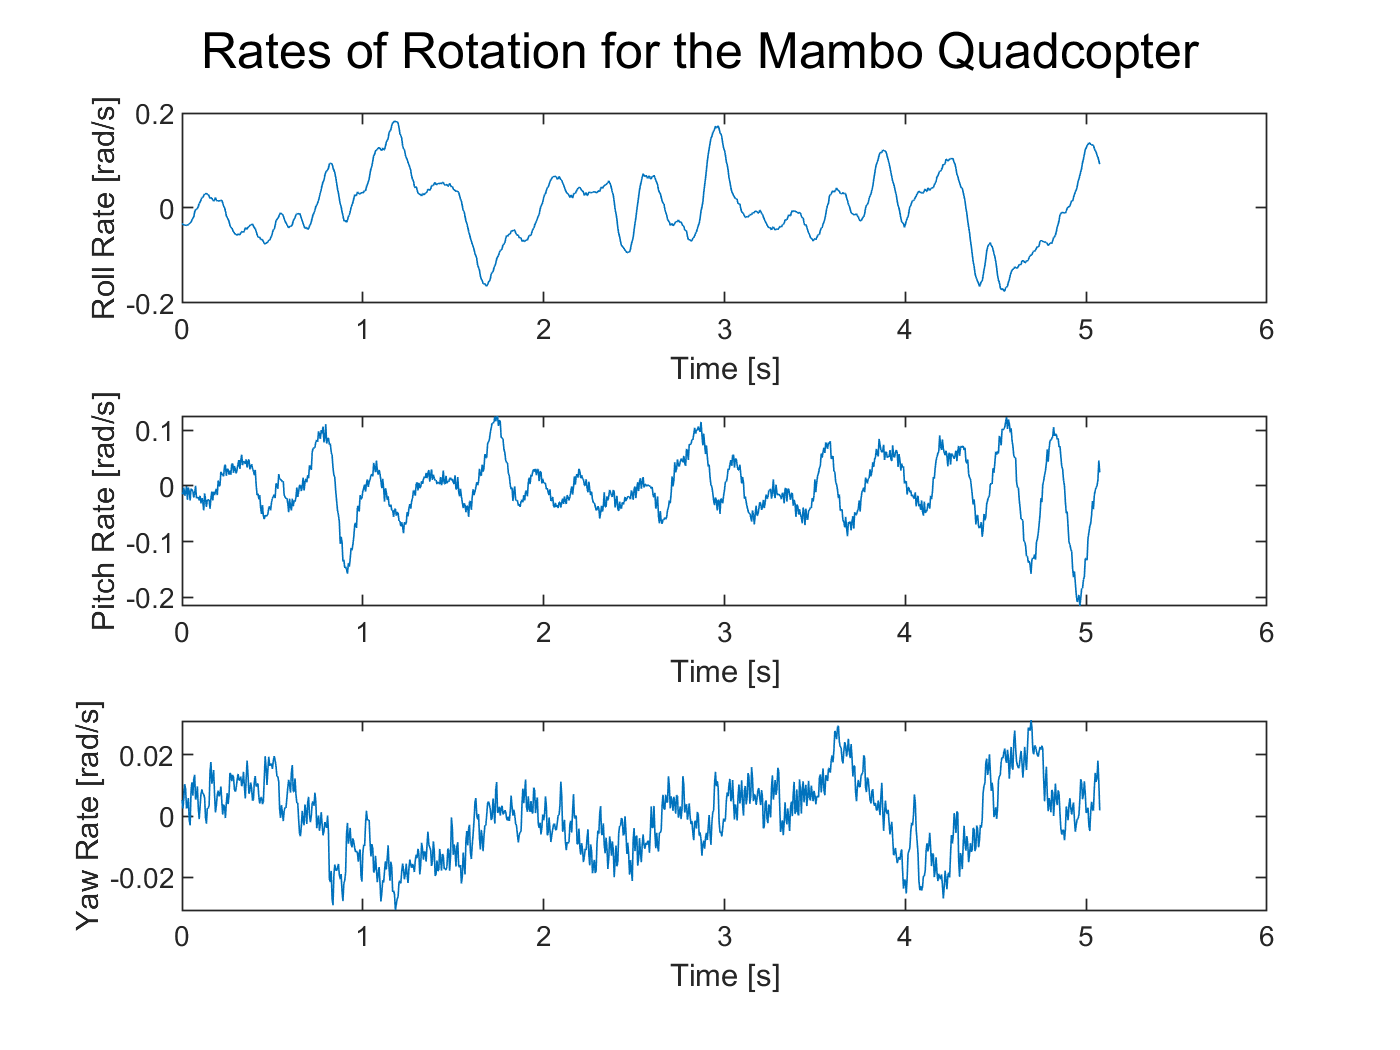


figure()
subplot(3,1,1)
plot(time,p)
xlabel('Time [s]')
ylabel('Roll Rate [rad/s]')

subplot(3,1,2)
plot(time,q)
xlabel('Time [s]')
ylabel('Pitch Rate [rad/s]')

subplot(3,1,3)
plot(time,r)
xlabel('Time [s]')
ylabel('Yaw Rate [rad/s]')

sgtitle('Rates of Rotation for the Mambo Quadcopter')

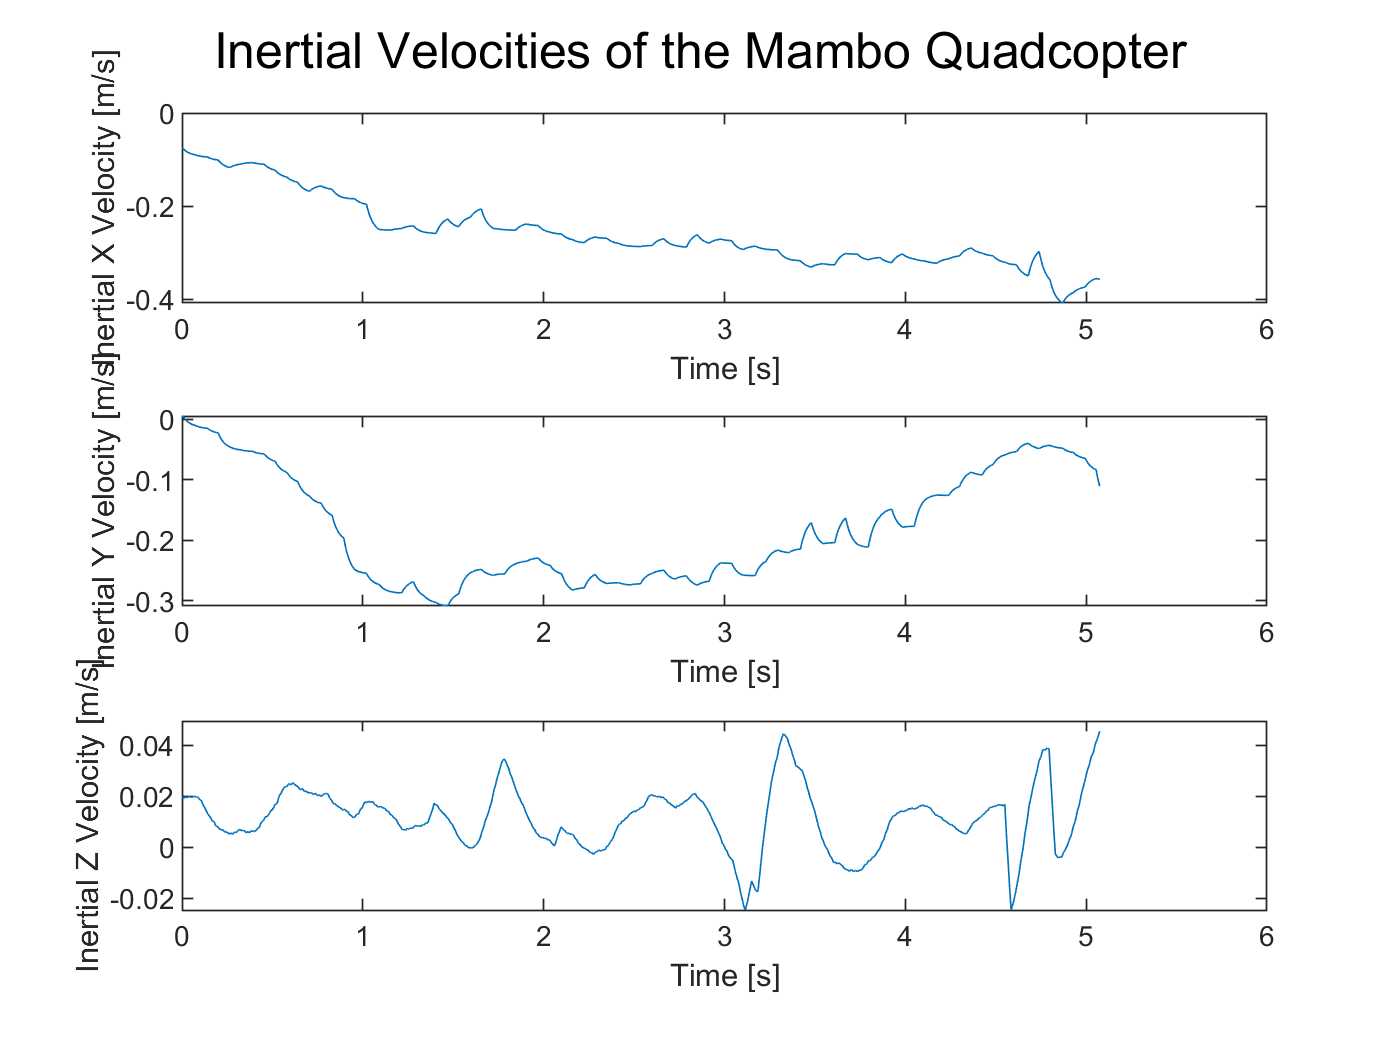


figure()
subplot(3,1,1)
plot(time,Vx)
xlabel('Time [s]')
ylabel('Inertial X Velocity [m/s]')

subplot(3,1,2)
plot(time,Vy)
xlabel('Time [s]')
ylabel('Inertial Y Velocity [m/s]')

subplot(3,1,3)
plot(time,-Vz)
xlabel('Time [s]')
ylabel('Inertial Z Velocity [m/s]')

sgtitle('Inertial Velocities of the Mambo Quadcopter')

### Discussion

The Mambo copter clearly was stable using the feedback gains calculated in problem 1 of this homework set.  Additionally, it performed the movement of 1 meter in both the +X- and +Y-direction satisfactorily, although instead of doing one movement and then the other (like in the simulation), it performed them both at the same time.  Regardless, it performed as expected.

The rotation rates and euler angles are different from the simulation to the quadcopter.  This is most likely due to the fact that the simulation does not take into account a few factors, namely: 

- Static in the sensor readings.  The simulation "knows" exactly what the measure of each aspect of the quadcopter is at all times, whereas the actual quadcopter does not have this capability.

- The quadcopter is not perfectly able to follow the desired responses from the model.  This is due to the fact that the motors must have time to spin up, the processor requires time to compute the needed inputs, etc.

Additionally, the model we used for the simulation was a linearized model of the quadcopter.  As opposed to the actual copter, it does not take into account all of the variations of thrust, moments, etc.  However, we justify this simplification because as models get more complex, it is nigh impossible to model every single thing that may impact the copter's flight, and is very taxing in terms of computer processing power.

## Functions

function derivativeState = quadcopterSimulationLinOpenLoop(t,State)

Declare global and local constants.

global g I_x I_y I_z m R fb f1 f2 f3 f4 L M N G_body g_body
eta = 1 * 10 ^ (-3); % [N/(m/s)^2], drag per velocity squared
alpha = 2 * 10 ^ (-6); % [N*m/(rad/s)^2], moment per rate of rotation squared
k = 0.0024; % [N*m/N], moment per force of motors
refRR = 0;
refPR = 0;
refphi = 0;
reftheta = 0;
if t < 2
    refV = 2;
else
    refV = 0;
end
if (t > 10  && t < 12)
    refU = 2;
else
    refU = 0;
end
feedbackGainRollRate = 0.0016;
feedbackGainPitchRate = 0.00199;
feedbackGainYawRate = 0.004;
feedbackGainElevationAngle = 0.00449;
feedbackGainBankAngle = 0.0036;
feedbackGainAzimuth = 0.004;
velocityGainv = 6 * 10 ^(-2);
velocityGainu = 7.45 * 10 ^ (-2);

Extract variable from state vector.

x = State(1);
y = State(2);
z = State(3);
u = State(4);
v = State(5);
w = State(6);
p = State(7);
q = State(8);
r = State(9);
phi = State(10);
theta = State(11);
psi = State(12);

Calculate the forces and moments.

Thrust = (m * g);
f1 = -Thrust / 4;
f2 = -Thrust / 4;
f3 = -Thrust / 4;
f4 = -Thrust / 4;

A_aerodynamic_body = -eta * sqrt(u^2 + v^2 + w^2) * [u; v; w]; % [N], aerodynamic forces on vehicle
A_control_body = [0; 0; f1 + f2 + f3 + f4]; % [N], control forces on vehicle
fb = m * g_body + A_aerodynamic_body + A_control_body; % [N], vector of forces on quadcopter

G_aerodynamic_body = -alpha * sqrt(p^2 + q^2 + r^2) * [p; q; r]; % [N*m], aerodynamic moments on vehicleG
L = (R/sqrt(2)) * (f1 + f2 - f3 - f4) - feedbackGainRollRate * p + (feedbackGainBankAngle * ((refphi - phi) + (velocityGainv * (refV - v)))); % [N*m], control moment
M = (R/sqrt(2)) * (-f1 + f2 + f3 - f4) - feedbackGainPitchRate * q + (feedbackGainElevationAngle * ((reftheta - theta) - (velocityGainu * (refU - u)))); % [N*m], control moment
N = k * (f1 - f2 + f3 - f4) - feedbackGainYawRate * r - feedbackGainAzimuth * psi; % [N*m], control moment
G_control_body = [L; M; N]; % [N*m], total control moment
G_body = G_aerodynamic_body + G_control_body + 0; % [N*m], total moments on vehicle

Calculate the derivatives.

xDot = (u * cos(theta) * cos(psi)) + (v * (sin(phi) * sin(theta) * cos(psi) - cos(phi)...
    * sin(psi))) + w * (cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi));
yDot = (u * cos(theta) * sin(psi)) + (v * (sin(phi) * sin(theta) * sin(psi)...
    + cos(phi) * cos(psi))) + w * (cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi));
zDot = 0; %(-u * sin(theta))+(v * sin(phi) * cos(theta)) + (w * cos(phi) * cos(theta));

uDot = -g * theta;
vDot = g * phi;
wDot = 0;

psiDot = r;
phiDot = p;
thetaDot = q;

pDot = (1 / I_x) * (G_body(1));
qDot = (1 / I_y) * (G_body(2));
rDot = (1 / I_z) * (G_body(3));

derivativeState = [xDot yDot zDot uDot vDot wDot pDot qDot rDot phiDot thetaDot psiDot].';

end

Function that's used to plot results from both linearized and non-linearized models

This function takes in the time and results vectors from the ode45 function, as well as a title for plots.

function [] = plutter(time, results, titlestring)

Extract the results from the results vector

    x = results(:,1);
    y = results(:,2);
    z = results(:,3);
    u = results(:,4);
    v = results(:,5);
    w = results(:,6);
    p = results(:,7);
    q = results(:,8);
    r = results(:,9);
    phi = results(:,10);
    theta = results(:,11);
    psi = results(:,12);    

Create the figure, plot results

    figure();
    plot3(x, y, -z, "r*");
    xlabel('X Position');
    ylabel('Y Position');
    zlabel('Z Position');
    title(['Inertial Position for ', titlestring]);
    grid on
    
    figure();
    Fig1 = tiledlayout(3,1);
    title(Fig1, ['Inertial Velocity for ', titlestring]);
    nexttile();
    plot(time, u);
    title('X Velocity');
    xlabel('Time [sec]');
    ylabel('Vel [m/s]');
    
    nexttile();
    plot(time, v);
    title('Y Velocity');
    xlabel('Time [sec]');
    ylabel('Vel [m/s]');
    
    nexttile();
    plot(time, -w);
    title('Z Velocity');
    xlabel('Time [sec]');
    ylabel('Vel [m/s]');
    
    figure();
    Fig2 = tiledlayout(3,1);
    title(Fig2, ['Rotation Rates for ', titlestring]);
    nexttile();
    plot(time, p);
    title('Roll Rate');
    xlabel('Time [sec]');
    ylabel('Ang Vel [rad/s]');
    
    nexttile();
    plot(time, q);
    title('Pitch Rate');
    xlabel('Time [sec]');
    ylabel('Ang Vel [rad/s]');
    
    nexttile();
    plot(time, r);
    title('Yaw Rate');
    xlabel('Time [sec]');
    ylabel('Ang Vel [rad/s]');
    
    figure();
    Fig3 = tiledlayout(3,1);
    title(Fig3, ['Euler Angles for ', titlestring]);
    nexttile();
    plot(time, phi);
    title('Bank Angle');
    xlabel('Time [sec]');
    ylabel('Angle [rad]');
    
    nexttile();
    plot(time, theta);
    title('Elevation Angle');
    xlabel('Time [sec]');
    ylabel('Angle [rad]');
    
    nexttile();
    plot(time, psi);
    title('Azimuth');
    xlabel('Time [sec]');
    ylabel('Angle [rad]');
end
